# Control Rotary Encoder Knob

This example shows how to use the MATLAB® Support Package for Arduino® Hardware to control a 12-step rotary encoder with a built-in push button.

## Hardware Requirements

- Arduino Uno board

- SparkFun® 12-step rotary encoder with built-in push button

## Hardware Setup

Connect the rotary encoder to Arduino hardware:

- Connect the common pin C on encoder to GND pin on Arduino hardware.

- Connect the output A and B on encoder to digital pin 2 and 3 on Arduino hardware.

- Connect the ground pin on encoder to GND pin on Arduino hardware.

- Connect the push button pin on encoder to digital pin 4 on Arduino hardware.

Note: If you are using a different Arduino board than Uno, instead of using digital pin 2 and 3, use any two of the interrupt pins on your board. See [Arduino Interrupts](https://docs.arduino.cc/language-reference/en/functions/external-interrupts/attachInterrupt/) for more information about the available interrupt pins. 

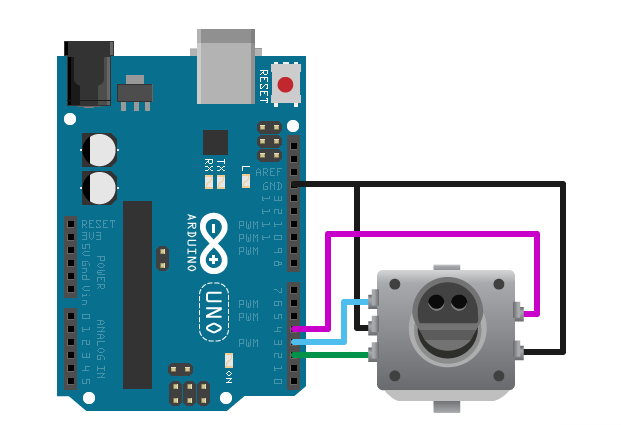

## Create Rotary Encoder Object

Create an arduino object, and include the `'RotaryEncoder'` library. 

   a = arduino('COM4','Uno','Libraries','RotaryEncoder')

Create rotary encoder object for knob, specifying the connected output channel A and channel B. 

   channelA = 'D2';
   channelB = 'D3';
   encoder = rotaryEncoder(a,channelA,channelB)

## Read Knob Position

The rotary encoder has 12 click positions for each revolution. Each click increases or decreases the count by 4, depending on the direction in which it is rotated. Therefore, the knob position can be represented by integers between 0 and 44.

Turn knob to starting position, and reset the count to 0.

    resetCount(encoder);

Add logic to display the encoder position when the pushbutton is pressed. If unpressed, the pushbutton pin returns 1. Otherwise, it returns 0.

   pushbutton = 'D4';
   configurePin(a,pushbutton,'Pullup');
   while(~readDigitalPin(a,pushbutton))
       count = readCount(encoder);
       pos = mod(count,48);
       fprintf('Current knob position: %d\n',pos);
       pause(1);
   end

## Clean Up

When the connection is no longer needed, clear the rotary encoder and arduino object.

  clear encoder a

*Copyright 2016 The MathWorks, Inc.*